%% plot_alpha_beta.mlx
clear; clc; close all;

% ===== Magnet parameters =====
MA = 1.05e6;
R  = 5e-3;   T_half = 2.5e-3;
W  = 5e-3;   H = 5e-3;   L = 2.5e-3;

% ===== Spacing range =====
d_all = [linspace(5e-3, 150e-3, 60), linspace(151e-3, 350e-3, 40)];

% ===== Cylindrical =====
fprintf('Computing cylindrical magnet coefficients...\n');

Computing cylindrical magnet coefficients...



[alpha_cy, beta_cy, dmin_cy] = correct_cylindermagnet_coeff(MA, R, T_half, d_all);

历时 1.490940 秒。



% ===== Cuboidal =====
fprintf('Computing cuboidal magnet coefficients...\n');

Computing cuboidal magnet coefficients...



[alpha_cu, beta_cu, dmin_cu] = correct_cuboidalmagnet_coeff(MA, W, H, L, d_all);

历时 0.843806 秒。


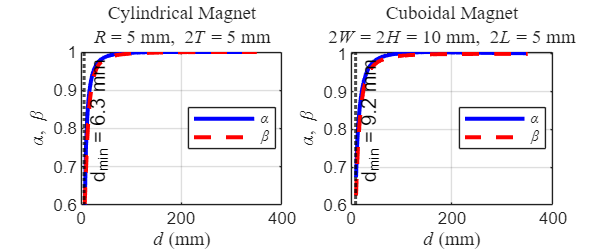



% ===== Plot (with Times New Roman) =====
figure('Position', [100 100 1100 450]);

subplot(1,2,1);
plot(d_all*1e3, alpha_cy, 'b-', 'LineWidth', 2); hold on;
plot(d_all*1e3, beta_cy,  'r--','LineWidth', 2);
xline(dmin_cy*1e3, 'k:', 'LineWidth', 1.5, ...
      'Label', sprintf('d_{min} = %.1f mm', dmin_cy*1e3), ...
      'LabelVerticalAlignment', 'top');
xlabel('\itd\rm (mm)', 'FontName','Times New Roman');
ylabel('\alpha,  \beta', 'FontName','Times New Roman');
title(sprintf('Cylindrical Magnet\n\\itR\\rm = %.0f mm,  2\\itT\\rm = %.0f mm', R*1e3, 2*T_half*1e3), ...
      'FontName','Times New Roman');
legend('\alpha', '\beta', 'Location', 'best', 'FontName','Times New Roman');
grid on; box on;

subplot(1,2,2);
plot(d_all*1e3, alpha_cu, 'b-', 'LineWidth', 2); hold on;
plot(d_all*1e3, beta_cu,  'r--','LineWidth', 2);
xline(dmin_cu*1e3, 'k:', 'LineWidth', 1.5, ...
      'Label', sprintf('d_{min} = %.1f mm', dmin_cu*1e3), ...
      'LabelVerticalAlignment', 'top');
xlabel('\itd\rm (mm)', 'FontName','Times New Roman');
ylabel('\alpha,  \beta', 'FontName','Times New Roman');
title(sprintf('Cuboidal Magnet\n2\\itW\\rm = 2\\itH\\rm = %.0f mm,  2\\itL\\rm = %.0f mm', 2*W*1e3, 2*L*1e3), ...
      'FontName','Times New Roman');
legend('\alpha', '\beta', 'Location', 'best', 'FontName','Times New Roman');
grid on; box on;